## Zadanie 1

**Podpunkt a)**

Tworzymy

- Dwa wektory `a1` i `a2` o wymiarach `1x4`

- Macierz jednostkową `A1` wymiaru `2x2`

- Dowolną macierz górnotrójkątną `A2` wymiaru `2x2`

a1 = [1 2 3 4];
a2 = [1 1 1 1];
A1 = eye(2);
A2 = [1 2; 0 3];

Następnie łączymy wektory `a1`, `a2` oraz macierze `A1`, `A2` w jedną dużą macierz `M`.

M = [[a1; a2]; [A1 A2]]

M =      1     2     3     4
     1     1     1     1
     1     0     1     2
     0     1     0     3


Wyliczamy wyznacznik oraz macierz odwrotną macierzy `M`

determinant = det(M)

determinant = -8

inverse = inv(M)

inverse =    -0.5000    1.0000    0.5000         0
         0    0.7500   -0.7500    0.2500
    0.5000   -0.5000         0   -0.5000
         0   -0.2500    0.2500    0.2500


Następnie zapisujemy do osobnych zmiennych

- Pierwszą kolumnę macierzy

- Trzeci wiersz macierzy

- Drugi i trzeci element czwartego wiersza macierzy

- Podmacierz od elementu `(2,2)` do elementu `(3,4)`

first_column = M(:,1)

first_column =      1
     1
     1
     0


third_row = M(3,:)

third_row =      1     0     1     2


second_and_third_element_of_fourth_row = M(4,2:3)

second_and_third_element_of_fourth_row =      1     0


submatrix = M(2:3,2:4)

submatrix =      1     1     1
     0     1     2


**Podpunkt b)**

Zapisujemy dane z poprzedniego podpunktu do pliku `matrices.mat`

save matrices.mat

**Podpunkt c)**

Czyścimy zmienne, następnie ładujemy dla testu plik `matrices.mat`

clear

load matrices.mat

## Zadanie 2

Przywołujemy funkcję `validate(pesel)` z poprzednich zajęć.

function isValid = validate(pesel)
    pesel = num2str(pesel);
    
    if ~all(isstrprop(pesel, 'digit'))
        error('Dane wejściowe zawierają znaki nie będące cyframi');
    end
    
    if length(pesel) ~= 11
        error('PESEL musi mieć dokładnie 11 cyfr');
    end

    digits = arrayfun(@(x) str2double(x), pesel);
    weights = [1 3 7 9 1 3 7 9 1 3 1];
    weightedSum = sum(digits .* weights);

    isValid = mod(weightedSum, 10) == 0;
end

Wczytujemy dane z pliku `example-pesel-numbers.txt`. Następnie dla każdego przykładowego numeru w tym pliku tekstowym sprawdzamy czy jest poprawnym numerem PESEL czy nie, ponadto zapisujemy płeć.

% Read PESEL numbers from the text file
pesel_numbers = readlines('example-pesel-numbers.txt');

% Initialize empty vectors for storing results

        PESEL        IsValid      Sex   
    _____________    _______    ________

    "19220315474"       1       "Male"  
    "12345678903"       1       "Female"
    "19900101234"       0       "Null"  
    "19750505678"       0       "Null"  
    "19880912345"       0       "Null"  
    "19660214789"       0       "Null"  
    "19520818901"       0       "Null"  
    "19430101234"       1       "Male"  
    "19310707890"       0       "Null"  
    "19220315478"       0       "Null"  
    "19130912345"       0       "Null"  
    "19040505678"       0       "Null"  
    "09040505678"       0       "Null"  



pesels_amount = length(pesel_numbers);
validity = zeros(pesels_amount, 1);
sex = strings(pesels_amount, 1);

for i = 1:pesels_amount
    pesel = pesel_numbers(i);
    digits = arrayfun(@(x) str2double(x), num2str(pesel));

         name             date        open      max       min      close       volume      close_open_difference    max_min_difference
    _______________    __________    ______    ______    ______    ______    __________    _____________________    __________________

    {'06MAGNA'    }    2.0141e+07      2.33       2.5      2.33      2.45          7999             0.12                    0.17      
    {'08OCTAVA'   }    2.0141e+07      0.86      0.86      0.86      0.86          4230                0                       0      
    {'4FUNMEDIA'  }    2.0141e+07      6.42      6.68      6.41      6.41          5903            -0.01                    0.27      
    {'ABCDATA'    


    isValid = validate(pesel);
    validity(i) = isValid;

    if isValid
        if mod(digits(10), 2) == 0
            sex(i) = 'Female';

ans =    719   719     3


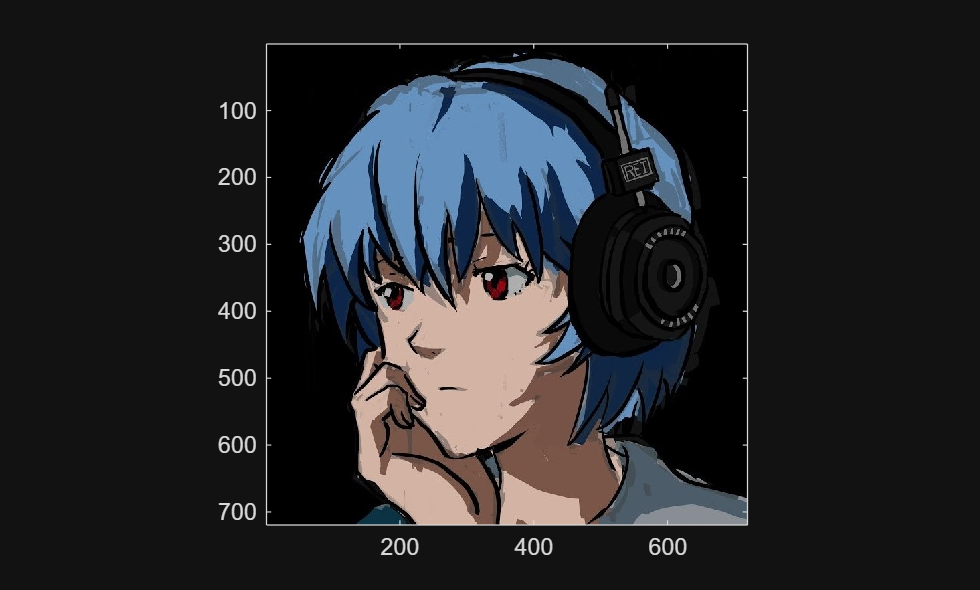

        else
            sex(i) = 'Male';
        end
    else

        sex(i) = 'Null';
    end
end

Wyniki zapisujemy w tabeli `pesel_table` którą eksportujemy do pliku `pesel-table.xlsx`

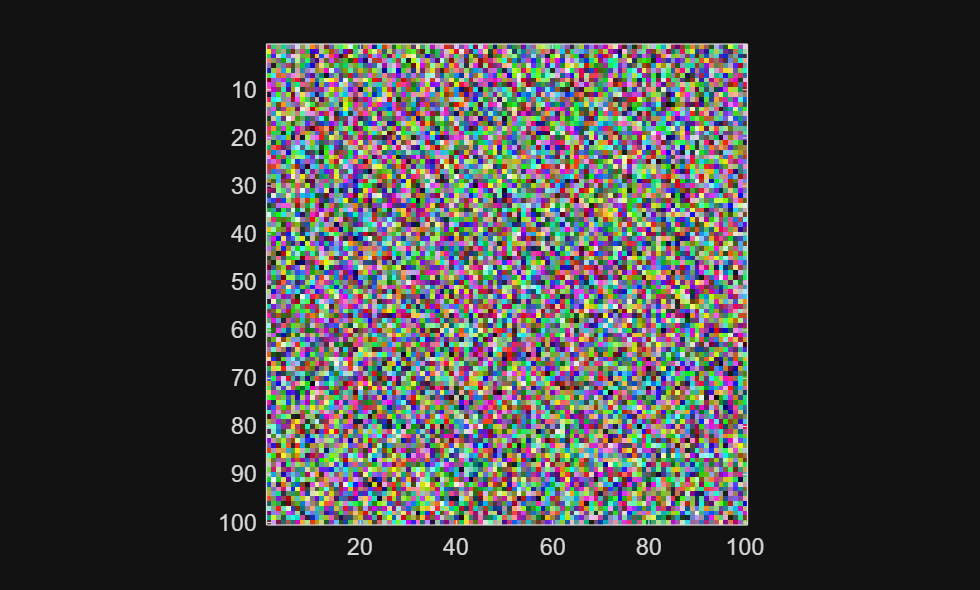

pesel_table = table(pesel_numbers, validity, sex, 'VariableNames', {'PESEL', 'IsValid', 'Sex'});
writetable(pesel_table, 'pesel-table.xlsx');
disp(pesel_table);

## Zadanie 3

Wczytujemy dane z pliku `stocks.csv` i dla każdego wiersza obliczamy różnice `close - open` oraz `max - min`. Wyniki zapisujemy w kolumnach `close_open_difference` i `max_min_difference`

table = readtable('stocks.csv');
table.close_open_difference = table.close - table.open;
table.max_min_difference = table.max - table.min;
disp(table)

## Zadanie 4

Wczytujemy plik graficzny `.jpg` do macierzy `M`.

M = imread('rei.jpg');

Sprawdzamy wymiary tej macierzy.

size(M)

Pierwsze dwa wymiary odpowiadają rozdzielczości pliku graficznego, a pozostały 3 wymiar odpowiada kanałom kolorów czerwonego, zielonego i niebieskiego

Wyświetlamy obraz na podstawie macierzy `M`

image(M)
axis image;

### Eksperymentowanie z generowaniem obrazów

**1. Losowy szum**

M = rand(100, 100, 3);
image(M);
axis image;

**2. Efekt anaglifu**

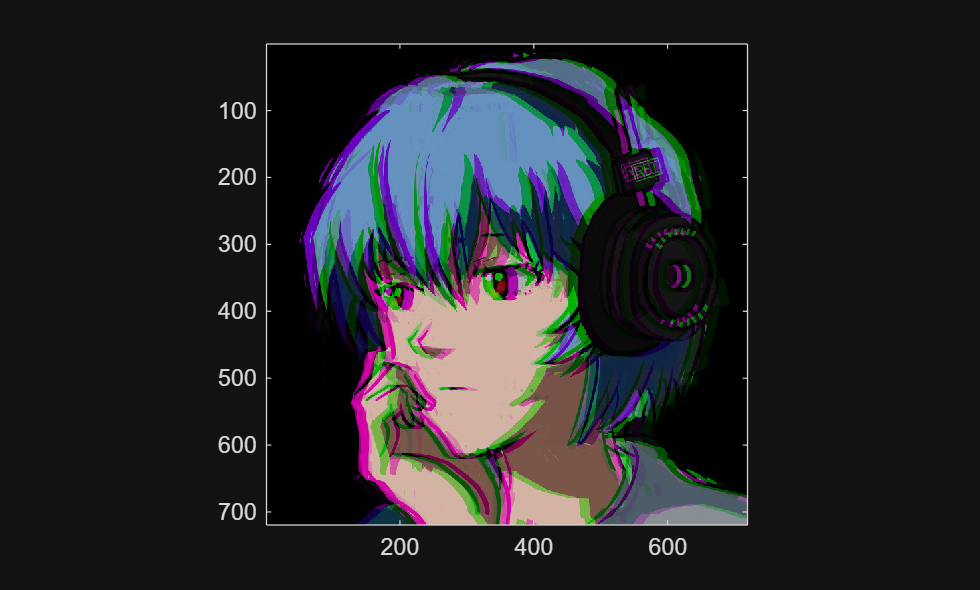

M = imread('rei.jpg');


[rows, cols, ~] = size(M);

green_shift = 15;

G = M(:,:,2);  % Green channel
G_shifted = G;  % Initialize G_shifted as G

% Shift the green channel
G_shifted(:, green_shift+1:end) = G(:, 1:end-green_shift);

M(:,:,2) = G_shifted;

image(M);
axis image;

**3. Trójkąt Sierpińskiego**

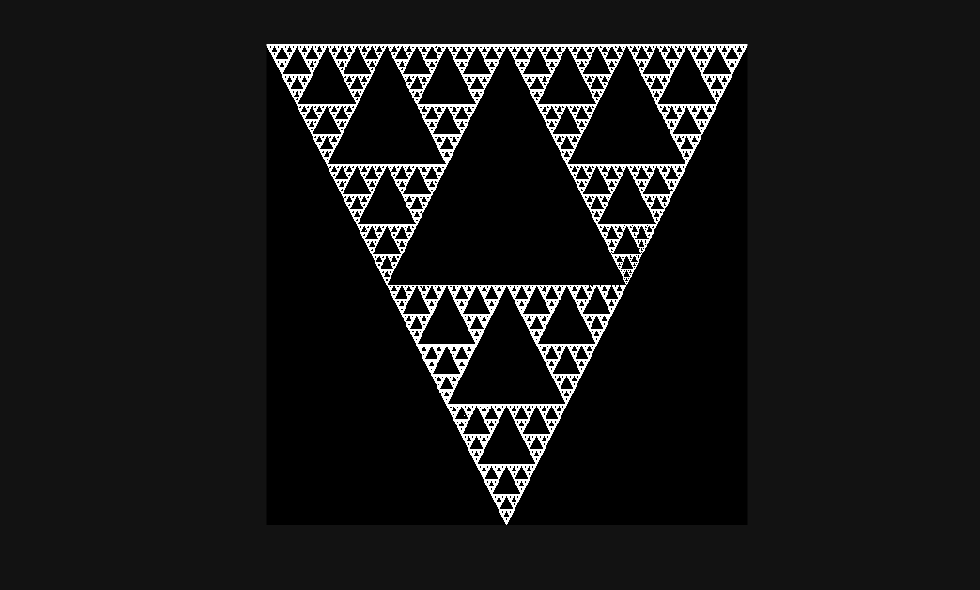

n = 512; % Size of the image
M = zeros(n); % Empty matrix
p1 = [1, 1]; % Top vertex of the triangle
p2 = [n, 1]; % Bottom left vertex
p3 = [n/2, n]; % Bottom right vertex

% Initial random point within the triangle
point = [randi(n), randi(n)];

% Number of iterations
num_iter = 1000000;

% Generate the Sierpiński triangle
for i = 1:num_iter
    % Choose a random vertex
    choice = randi(3);
    if choice == 1
        point = (point + p1) / 2;
    elseif choice == 2
        point = (point + p2) / 2;
    else
        point = (point + p3) / 2;
    end
    % Mark the point in the matrix

    M(round(point(2)), round(point(1))) = 1;
end

% Convert M to a 3D matrix for display
Image = zeros(n, n, 3);
Image(:,:,1) = M;
Image(:,:,2) = M;
Image(:,:,3) = M;

% Display the Sierpiński triangle
image(Image);
axis image;
axis off;